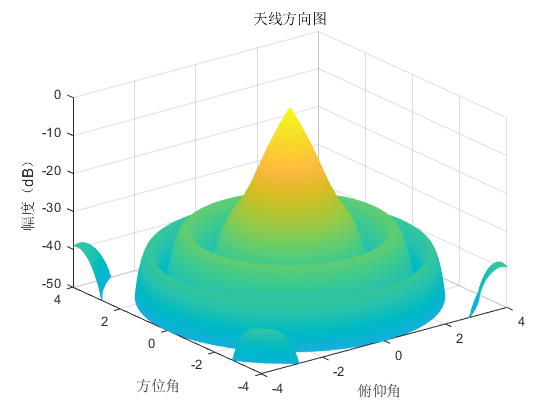

clc;
clear;
tic
%定义参数
theta=-4:0.01:4;
phi=-4:0.01:4;
%简化高斯方向图
% deg0_1=2.2;  %第一零点
% db0_1=-42;   %第一零点增益
% deg0_2=3.3;  %第二零点
% db0_2=-47;   %第二零点增益
% 
% deg1_1=2.7;  %第一副瓣
% db1_1=-32;   %第一副瓣增益
% deg1_2=3.6;  %第二副瓣
% db1_2=-38;   %第二副瓣增益

theta1=[0 1 1.5 2.2 3.3 2.7 3.6 4 5 6];

gain_db=[0 -20 -28 -42 -47 -32 -38 -50 -45 -55];

gain=10.^(gain_db/20);

% 插值方法
interp_method = 'spline'; % 选择插值方法，可以根据需要修改

% 生成更密集的角度点
theta_interp = 0:0.01:10;

% 使用插值方法逼近增益值
gain_interp = -abs(20*log10(interp1(theta1, gain, theta_interp, interp_method)));

m=length(theta);
n=length(phi);
F=zeros(m,n);
for i=1:m
    for j=1:n
        deg=(theta(i)^2+phi(j)^2)^0.5;
        index=fix(100*roundn(deg,-2)+1);
        F(i,j)=gain_interp(index);
    end
end

F_phi=zeros(n);

for i=1:n
    index=fix(abs(100*phi(i))+1);
    F_phi(i)=gain_interp(index);
end


%绘制方向图
figure 
mesh (phi,theta,F);
xlabel('俯仰角');
ylabel('方位角');
zlabel('幅度（dB）');
title('天线方向图')
zlim([-50,0]);

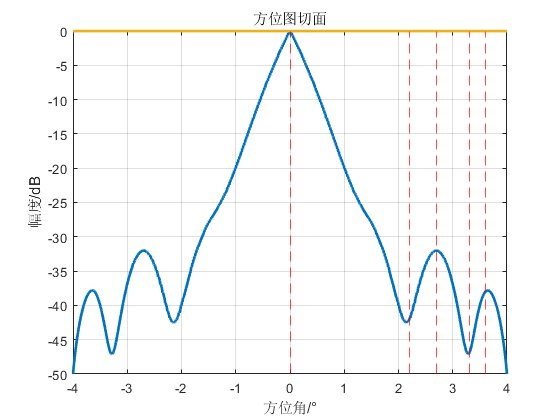

%画方位增益图
figure
plot(phi,F_phi,'linewidth',2);
title('方位图切面');
xlabel('方位角/°');
ylabel('幅度/dB');
xline([0 2.2 3.3 2.7 3.6],'r--')
grid on; hold on;

toc

历时 0.905886 秒。
